# MPO 651 - Assignment #1 Spring 2020 (due to 3/5)              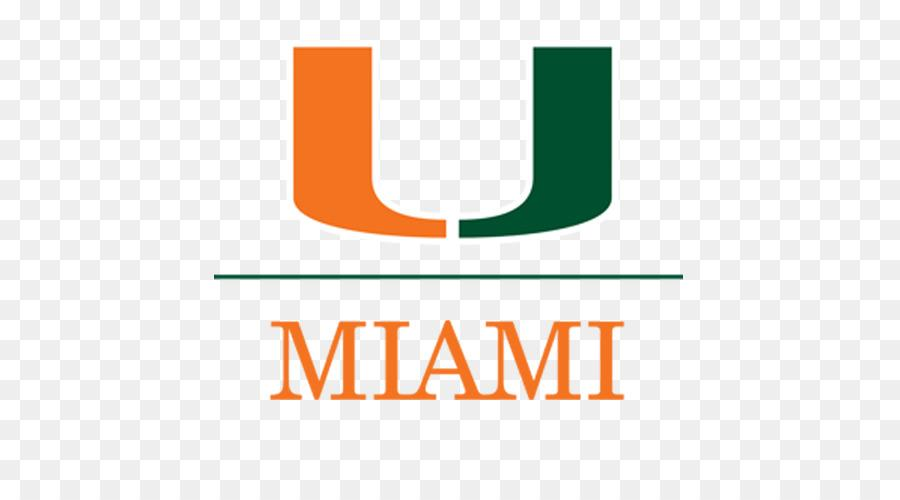

## Ivenis Pita

#### 1- Loading and organizing data

clear variables
close all
clc

%% var definition
mainfolder='/Users/ivenispita/Documents/UM_PhD/tide_gauge_data_BR/all_data';
foldernames={'10620_Santana';'30149_Madeira';'40141_Salvador';...
    '50140_Ilha_Fiscal';'50250_Cananeia';'60380_Rio_Grande'};
min_time=[];
max_time=[];
%% Load data
for k=1:size(foldernames,1)
    stn_folder=foldernames{k};
    load([mainfolder '/' stn_folder '/mat_' stn_folder(1:5) '.mat']);
    eval(['mat_' stn_folder(1:5) '(:,1)=julian(gregorian(mat_' stn_folder(1:5) '(:,1)));'])
    eval(['stn_' num2str(k) '=mat_' stn_folder(1:5) ';'])
    clear mat* title
    min_time=[min_time eval(['stn_' num2str(k) '(1,1);'])];%get initial time at each station
    max_time=[max_time eval(['stn_' num2str(k) '(end,1);'])];%get initial time at each station
end

%organizing time
time=min(min_time):1/24:max(max_time);
time=julian(gregorian(time));
stn_all=[];
for l=1:size(foldernames,1)
    stn_full=nan(size(time));
    eval(['stn_data=stn_' num2str(l) ';']);
    [ind1,loc1]=ismember(stn_data(:,1),time);
    [ind2,loc2]=ismember(time,stn_data(:,1));
    stn_full(ind2)=stn_data(ind1,2);
    stn_all=[stn_all stn_full];
end
stn_all=[stn_all time];

#### 2- Brief quality control

%Stn1
stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1)=stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1)-nanmean(stn_all(1:find(stn_all(:,7)==julian(1979,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(1979,1,1,0)):find(stn_all(:,7)==julian(1992,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(1995,1,1,0)):find(stn_all(:,7)==julian(1999,1,1,0)),1));
stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1)=stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1)-nanmean(stn_all(find(stn_all(:,7)==julian(2007,1,1,0)):find(stn_all(:,7)==julian(2010,1,1,0)),1));

%Stn2
stn_all(:,2)=stn_all(:,2)-nanmean(stn_all(:,2));
% stn_all(407070:438360,6)=fillgaps(stn_all(407070:438360,6));
%Stn3
stn_all(490000:500000,3)=fillgaps(stn_all(490000:500000,3));
stn_all(:,3)=stn_all(:,3)-nanmean(stn_all(:,3));

%Stn4
stn_all(:,4)=stn_all(:,4)-nanmean(stn_all(:,4));

%Stn5
stn_all(300000:440000,5)=fillgaps(stn_all(300000:440000,5));
% stn_all(300000:440000,5)=fillgaps(stn_all(300000:440000,5));
stn_all(:,5)=stn_all(:,5)-nanmean(stn_all(:,5));

%Stn6
stn_all(stn_all(:,6)>=4,6)=nan;
stn_all(407070:438360,6)=fillgaps(stn_all(407070:438360,6));
stn_all(:,6)=stn_all(:,6)-nanmean(stn_all(:,6));

#### 3) Selecting periods

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
P1=stn_all(407065:438384,[2 5 6 7]);

%P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)
P2=stn_all(471433:482304,[1 2 3 4 7]);

%P3 10/2007 to 01/2014 (Stn 2, 3 and 4)
P3=stn_all(470185:524616,[2 3 4 7]);

#### 4) Ploting location of the stations

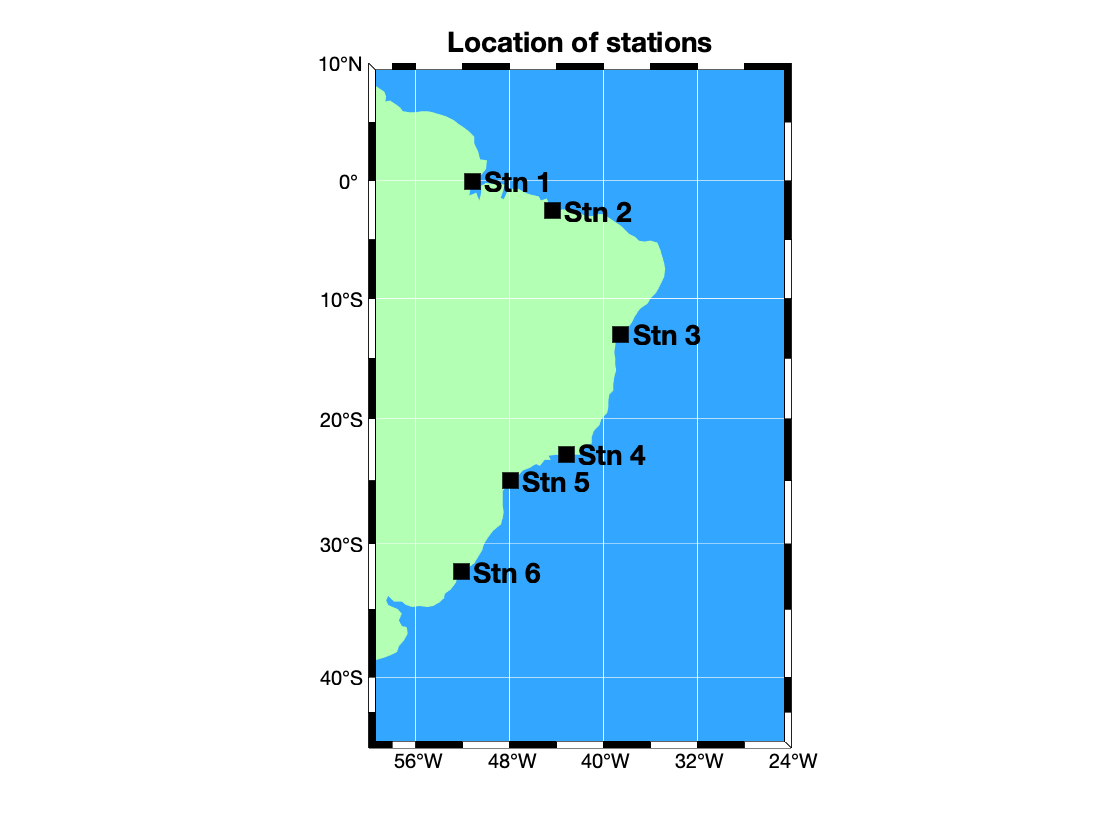

lat=[ -00.0567; -02.5650; -12.9733; -22.8967; -25.0167; -32.1383];
lon=[ -51.1817; -44.3783; -38.5167; -43.1667; -47.9250; -52.1033];

m_proj('miller','lat',[-45 10],'lon',[-60 -24]);
m_coast('patch',[.7 1 .7],'edgecolor','none');
m_grid('box','fancy','linestyle','-','gridcolor','w','backcolor',[.2 .65 1]);
stations={'Stn 1','Stn 2','Stn 3','Stn 4','Stn 5','Stn 6'};
hold on
m_plot(lon,lat,'s','Markersize',10,'MarkerEdgeColor','k','MarkerFaceColor','k');
hold on
m_text(lon+1,lat,stations,'s','fontsize',14,'fontweight','bold');
title('Location of stations','fontsize',14,'fontweight','bold');


set(gcf,'color','w');   % Need to do this otherwise 'print' turns the lakes black


#### 5) Harmonical analysis

%P1 (stn 2, 5, 6)
stn=[2, 5, 6];
for m=1:size(P1,2)-1
    [tide_struc,xout]=t_tide(P1(:,m),'interval',1,'start_time',gregorian(P1(1,end)),'latitude',lat(stn(m)));
    P1(:,m)=P1(:,m)-xout;
    clear tide_struc xout
end

   number of standard constituents used: 68
   Points used: 31319 of 31320
   percent of var residual after lsqfit/var original:  0.75 %
   Greenwich phase computed with nodal corrections applied to amplitude 
 and phase relative to center time
   Using nonlinear bootstrapped error estimates
   Generating prediction with nodal corrections, SNR is 2.000000
   percent of var residual after synthesis/var original:  0.77 %
-----------------------------------
date: 04-Mar-2020
nobs = 31320,  ngood = 31319,  record length (days) = 1305.00
start time: 04-Aug-2000 03:00:00
rayleigh criterion = 1.0
Greenwich phase computed with nodal corrections applied to amplitude \n and phase relative to center time

x0= -0.00406, x trend= 0

var(x)= 2.4684   var(xp)= 2.4485   var(xres)= 0.019055
percent var predicted/var original= 99.2 %

     tidal amplitude and phase with 95% CI estimates

tide   freq       amp     amp_err    pha    pha_err     snr
*SA   0.0001141    0.0379    0.015   259.31    22.16     


%P2 (stn 1, 2, 3, 4)
stn=[1, 2, 3, 4];
for m=1:size(P2,2)-1
    [tide_struc,xout]=t_tide(P2(:,m),'interval',1,'start_time',gregorian(P2(1,end)),'latitude',lat(stn(m)));
    P2(:,m)=P2(:,m)-xout;
    clear tide_struc xout
end

   number of standard constituents used: 67
   Points used: 10871 of 10872
   percent of var residual after lsqfit/var original:  1.43 %
   Greenwich phase computed with nodal corrections applied to amplitude 
 and phase relative to center time
   Using nonlinear bootstrapped error estimates
   Generating prediction with nodal corrections, SNR is 2.000000
   percent of var residual after synthesis/var original:  1.45 %
-----------------------------------
date: 04-Mar-2020
nobs = 10872,  ngood = 10871,  record length (days) = 453.00
start time: 08-Dec-2007 03:00:00
rayleigh criterion = 1.0
Greenwich phase computed with nodal corrections applied to amplitude \n and phase relative to center time

x0= 0.0107, x trend= 0

var(x)= 0.75679   var(xp)= 0.74594   var(xres)= 0.010999
percent var predicted/var original= 98.6 %

     tidal amplitude and phase with 95% CI estimates

tide   freq       amp     amp_err    pha    pha_err     snr
*SA   0.0001141    0.2594    0.020   117.55     3.89  1.8e


%P3 (stn 2, 3, 4)
stn=[2, 3, 4];
for m=1:size(P3,2)-1
    [tide_struc,xout]=t_tide(P3(:,m),'interval',1,'start_time',gregorian(P3(1,end)),'latitude',lat(stn(m)));
    P3(:,m)=P3(:,m)-xout;
    clear tide_struc xout
end

   number of standard constituents used: 68
   Points used: 54431 of 54432
   percent of var residual after lsqfit/var original:  0.33 %
   Greenwich phase computed with nodal corrections applied to amplitude 
 and phase relative to center time
   Using nonlinear bootstrapped error estimates
   Generating prediction with nodal corrections, SNR is 2.000000
   percent of var residual after synthesis/var original:  0.33 %
-----------------------------------
date: 04-Mar-2020
nobs = 54432,  ngood = 54431,  record length (days) = 2268.00
start time: 17-Oct-2007 03:00:00
rayleigh criterion = 1.0
Greenwich phase computed with nodal corrections applied to amplitude \n and phase relative to center time

x0= -0.0141, x trend= 0

var(x)= 2.5188   var(xp)= 2.5105   var(xres)= 0.0082727
percent var predicted/var original= 99.7 %

     tidal amplitude and phase with 95% CI estimates

tide   freq       amp     amp_err    pha    pha_err     snr
 SA   0.0001141    0.0059    0.004   289.05    41.96     

#### 6) Scattermatrix

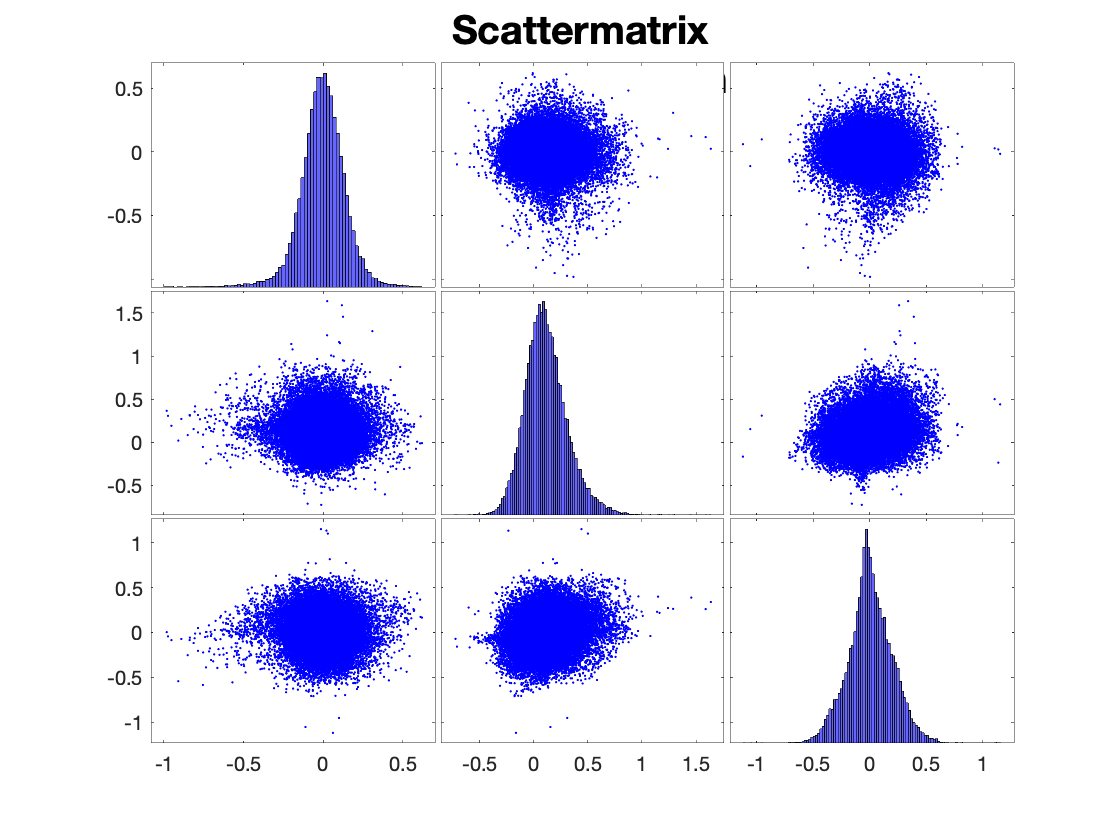

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
% group={'St-2','St-5','St-6'};
figure, 
gplotmatrix(P1(:,1:end-1))
title({'Scattermatrix';'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)

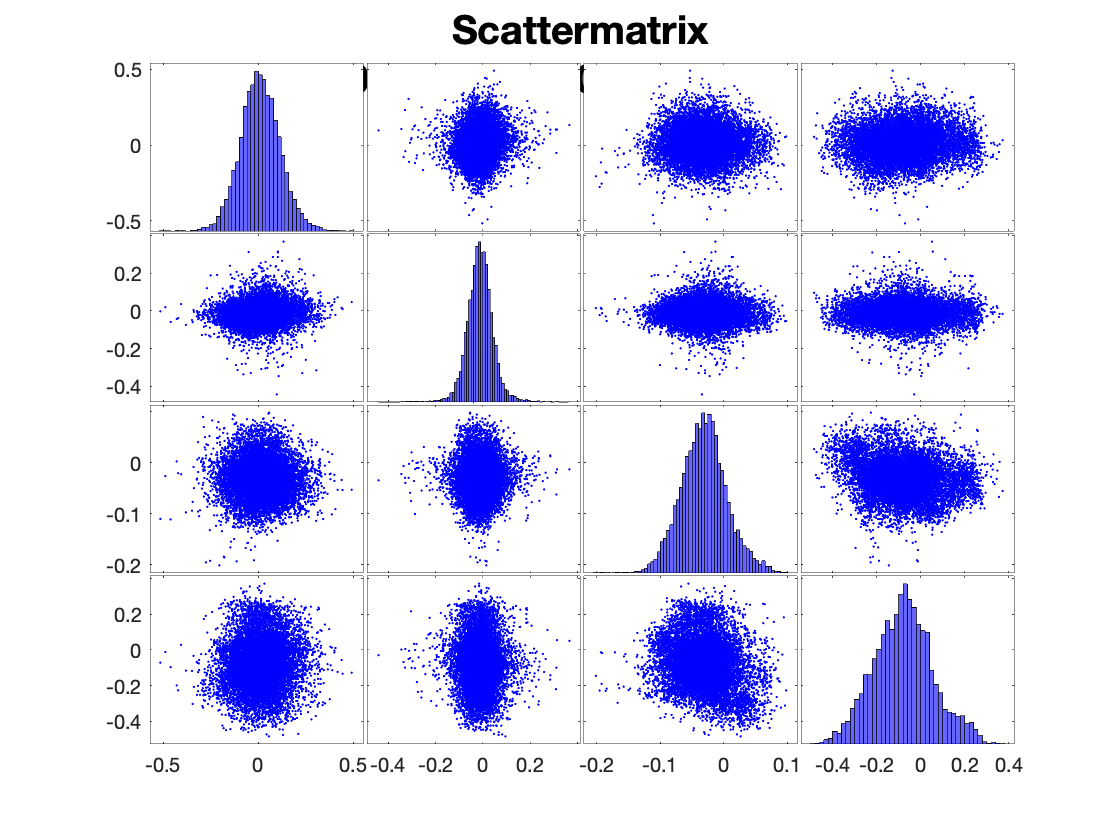

%P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)
figure, 
gplotmatrix(P2(:,1:end-1))
title({'Scattermatrix';'P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)

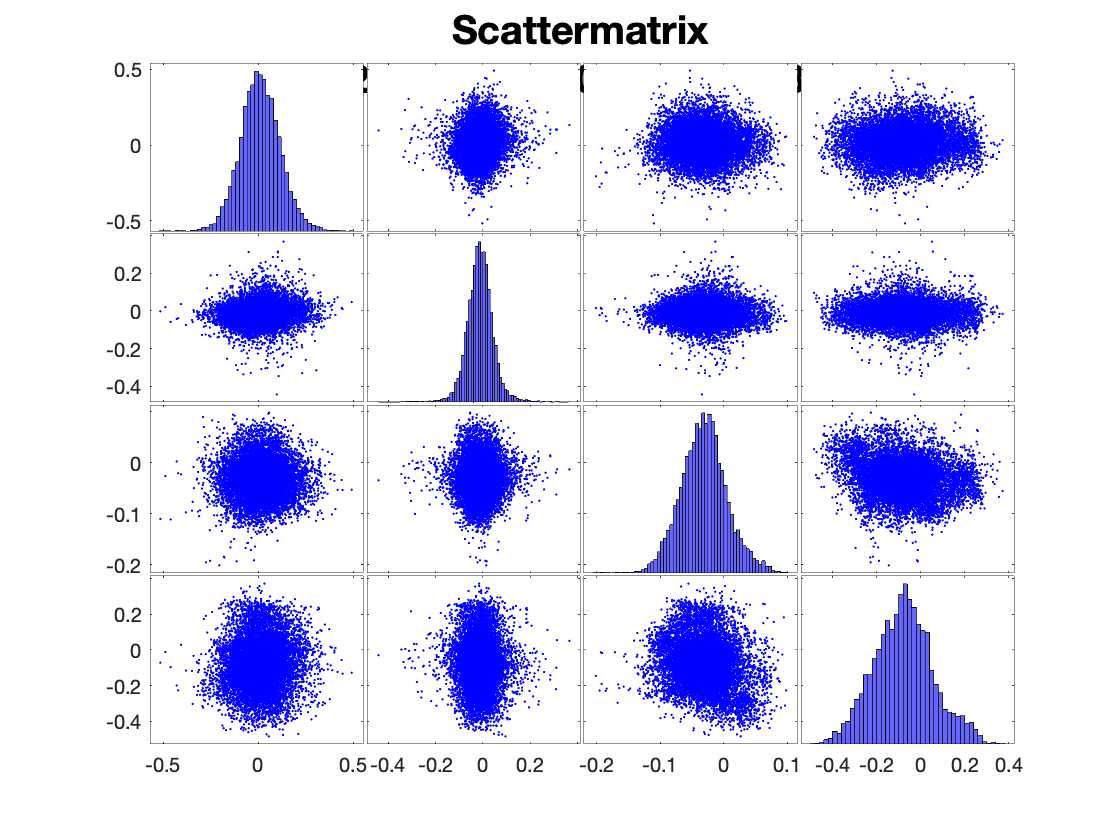

%P3 10/2007 to 01/2014 (Stn 2, 3 and 4)
figure, 
gplotmatrix(P2(:,1:end-1))
title({'Scattermatrix';'P3 10/2007 to 01/2014 (Stn 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)

#### 7) Covariance Matrix

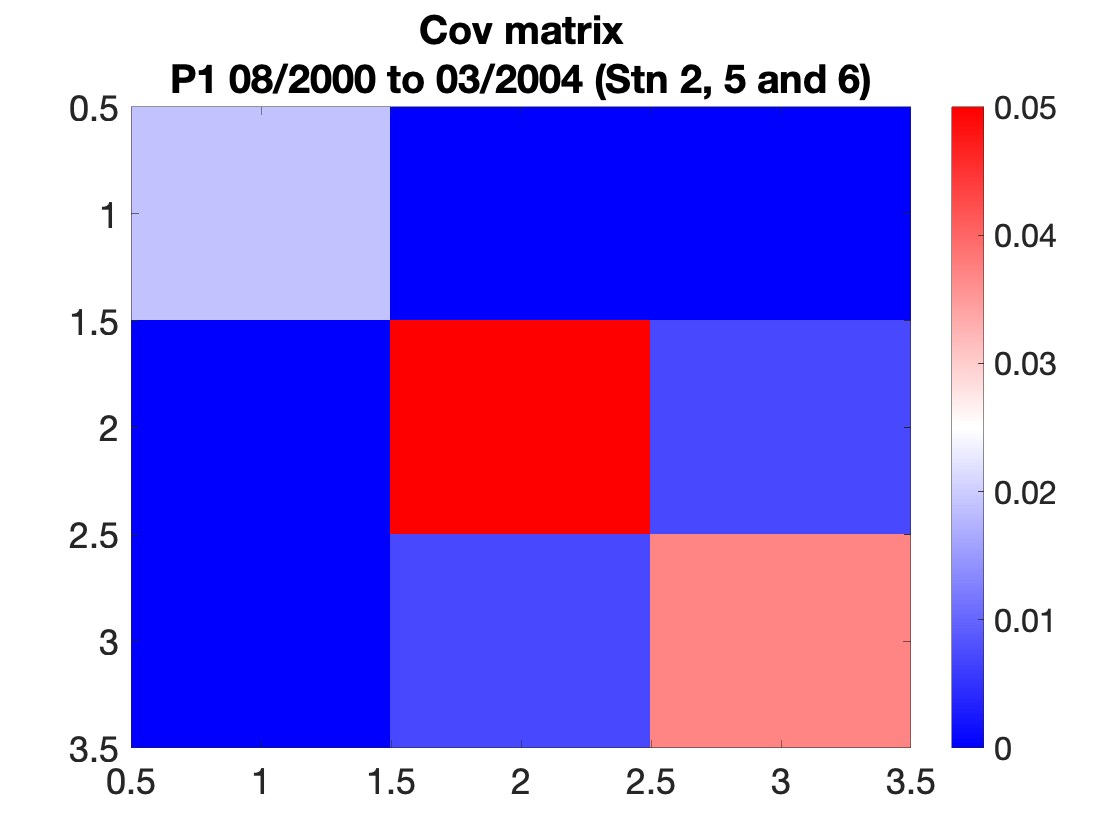

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
n=size(P1,1);
cov_p1=(P1(:,1:end-1)'*P1(:,1:end-1))/n;
figure
imagesc(cov_p1)
title({'Cov matrix'; 'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([0 .05])

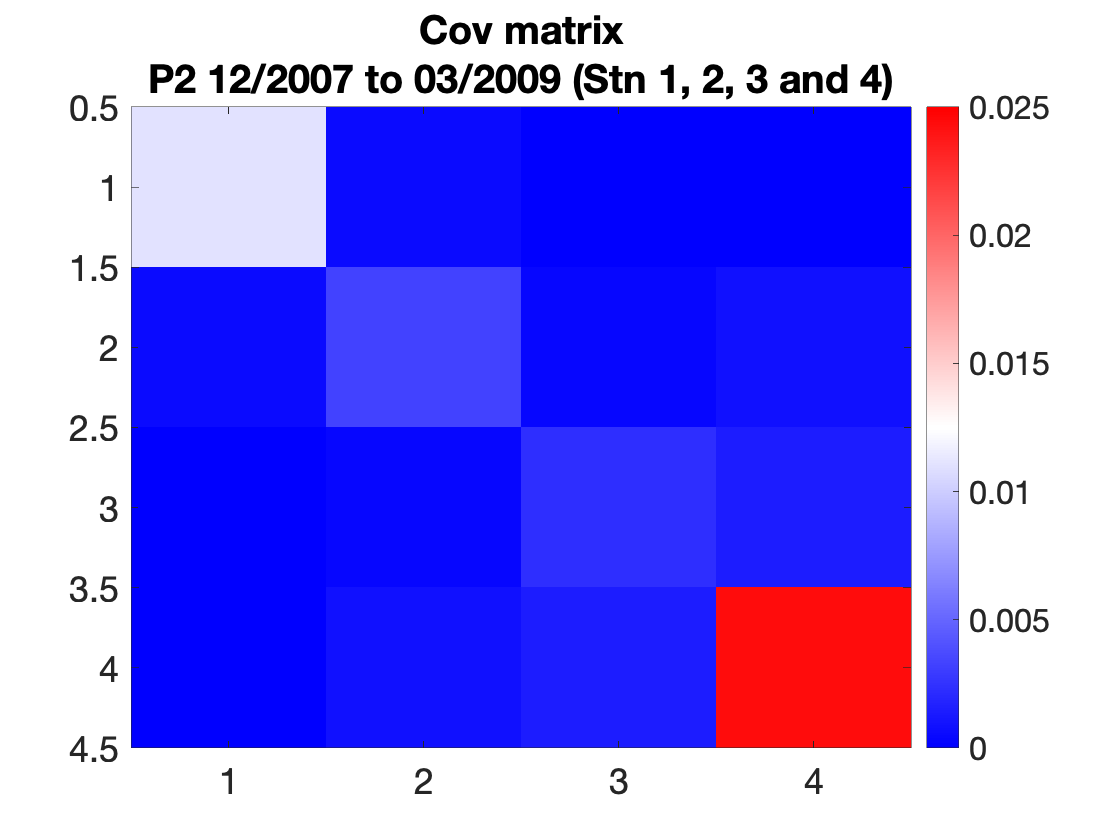

%P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)
n=size(P2,1);
cov_p2=(P2(:,1:end-1)'*P2(:,1:end-1))/n;
figure
imagesc(cov_p2)
title({'Cov matrix'; 'P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([0 .025])

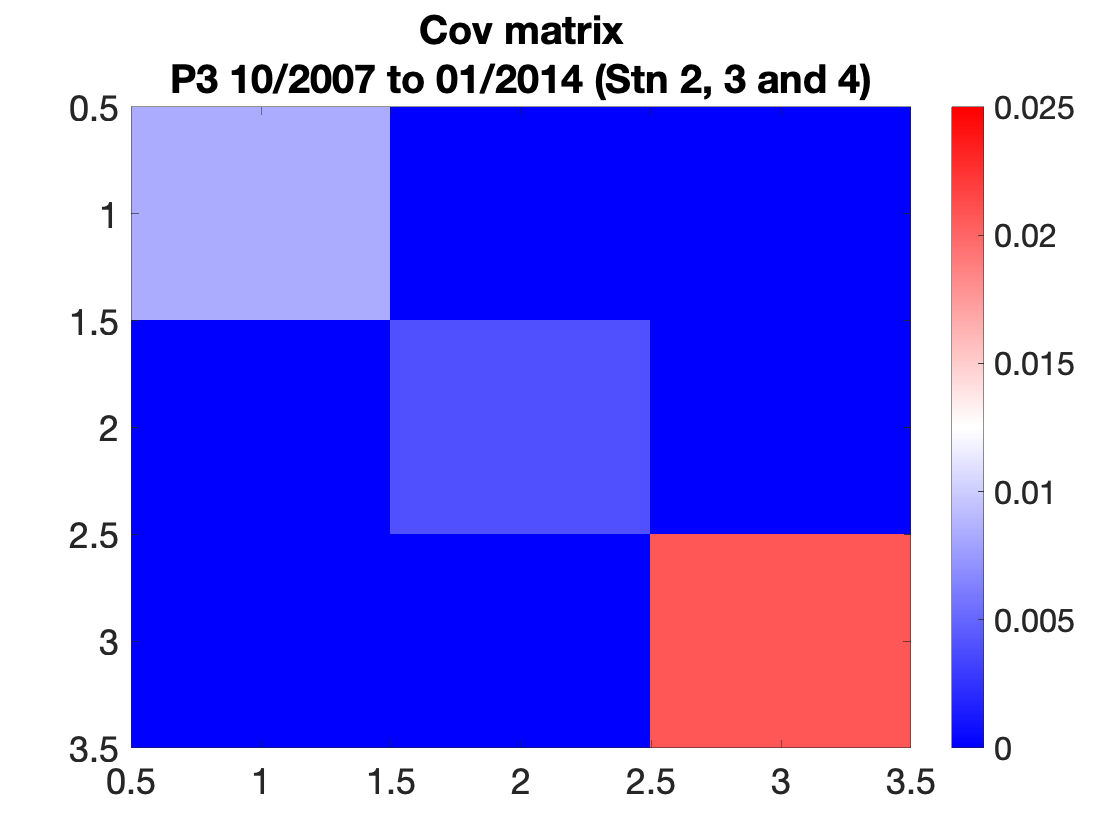

%P3 10/2007 to 01/2014 (Stn 2, 3 and 4)
n=size(P3,1);
cov_p3=(P3(:,1:end-1)'*P3(:,1:end-1))/n;
figure
imagesc(cov_p3)
title({'Cov matrix'; 'P3 10/2007 to 01/2014 (Stn 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([0 0.025])

#### 8) Corr Matrix

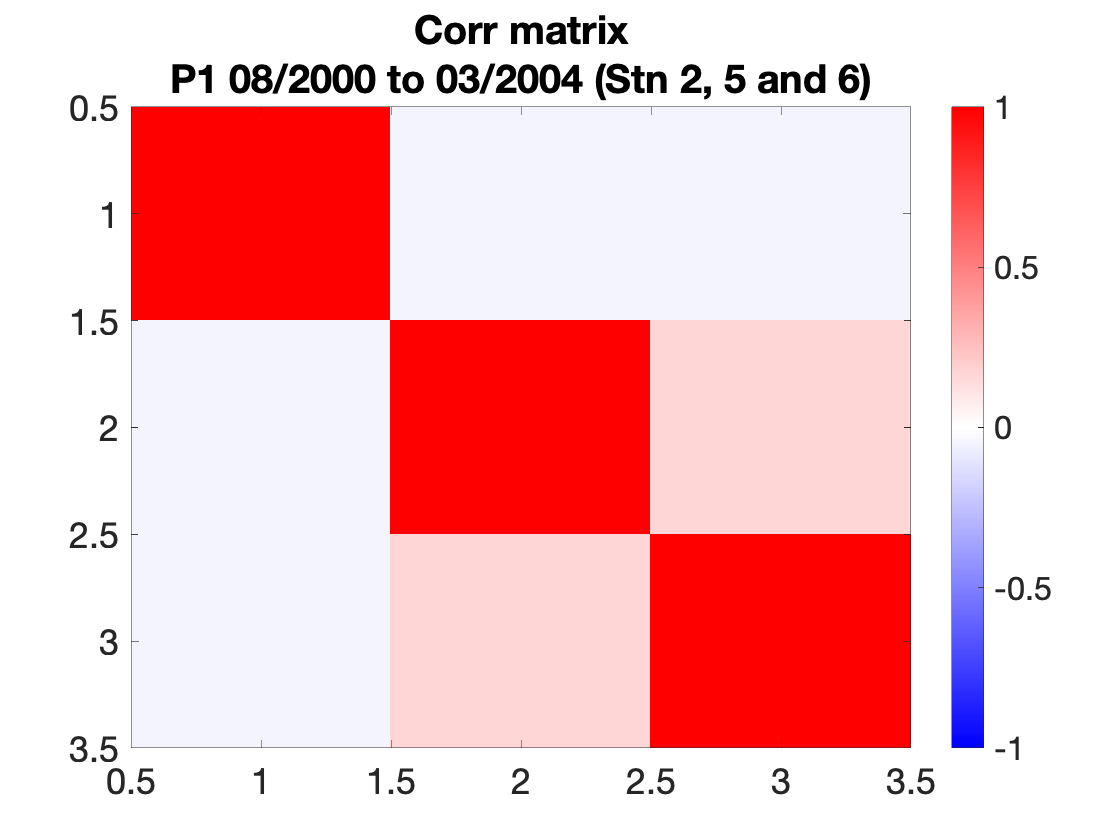

%P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
cor_p1=corrcov(cov_p1);
figure
imagesc(cor_p1)
title({'Corr matrix'; 'P1 08/2000 to 03/2004 (Stn 2, 5 and 6)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-1 1])

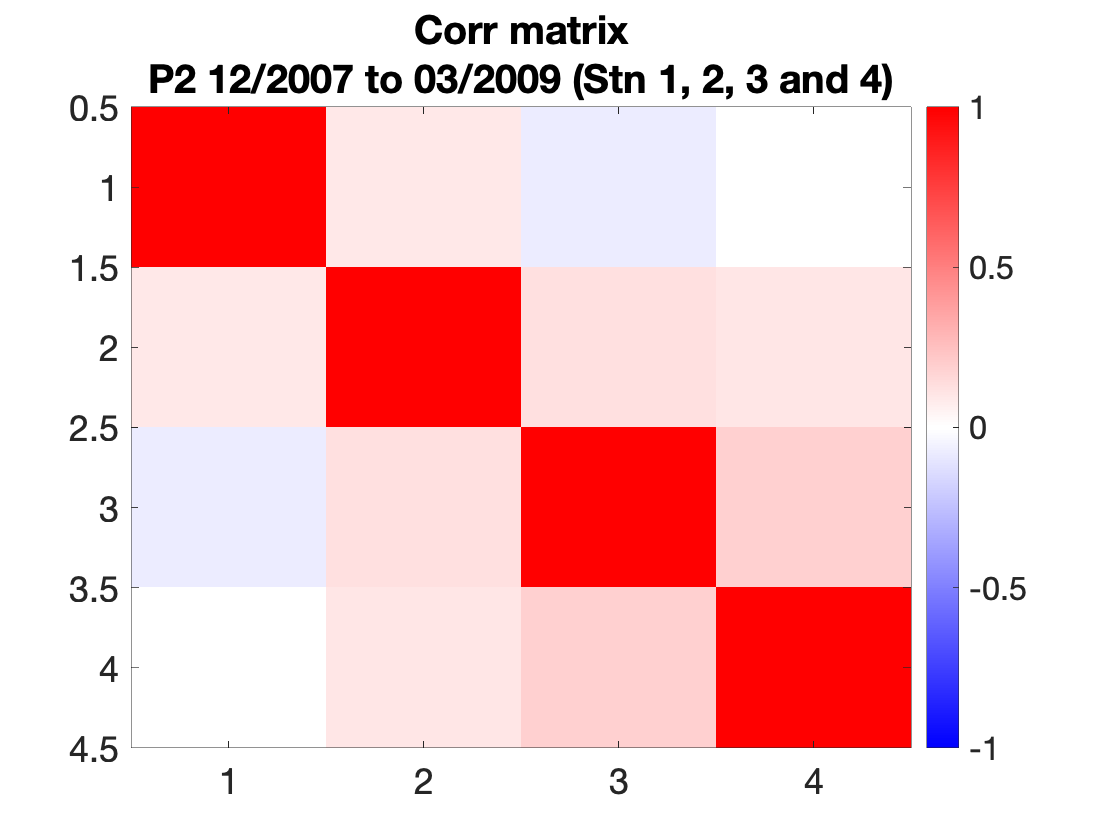

%P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)
cor_p2=corrcov(cov_p2);
figure
imagesc(cor_p2)
title({'Corr matrix'; 'P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-1 1])

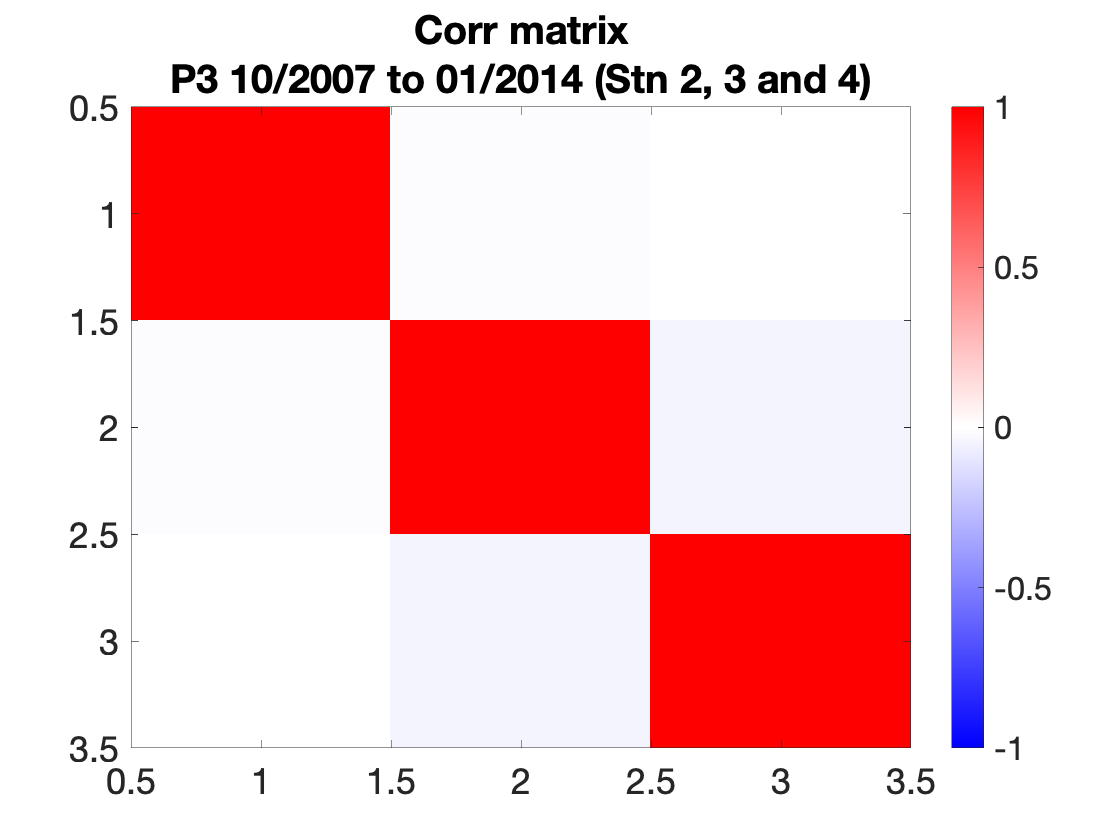

%P3 10/2007 to 01/2014 (Stn 2, 3 and 4)
cor_p3=corrcov(cov_p3);
figure
imagesc(cor_p3)
title({'Corr matrix'; 'P3 10/2007 to 01/2014 (Stn 2, 3 and 4)'},'FontSize',18)
set(gca,'FontSize',18)
colorbar
colormap(redblue)
caxis([-1 1])

#### 9)EOF/PC

%% P1 08/2000 to 03/2004 (Stn 2, 5 and 6)
[a b]=size(P1);
P1_sqr=repmat(P1(:,1:end-1)',[1,1,b-1]);
P1_sqr=permute(P1_sqr,[1,3,2]);
[eofmap_p1,pc_p1,expv_p1] = eof(P1_sqr,9);
%Explained variance of each PC
T_p1 = table(expv_p1(1),expv_p1(2),expv_p1(3),expv_p1(4),expv_p1(5),expv_p1(6),expv_p1(7),expv_p1(8),expv_p1(9), 'VariableNames', {'PC 1','PC 2','PC 3','PC 4','PC 5','PC 6','PC 7','PC 8','PC 9'})

T_p1 = 1×9 table
     PC 1      PC 2     PC 3        PC 4       PC 5    PC 6    PC 7       PC 8          PC 9   
    ______    ______    _____    __________    ____    ____    ____    __________    __________

    46.843    33.117    20.04    9.6178e-15     0       0       0      2.3742e-16    8.5861e-17


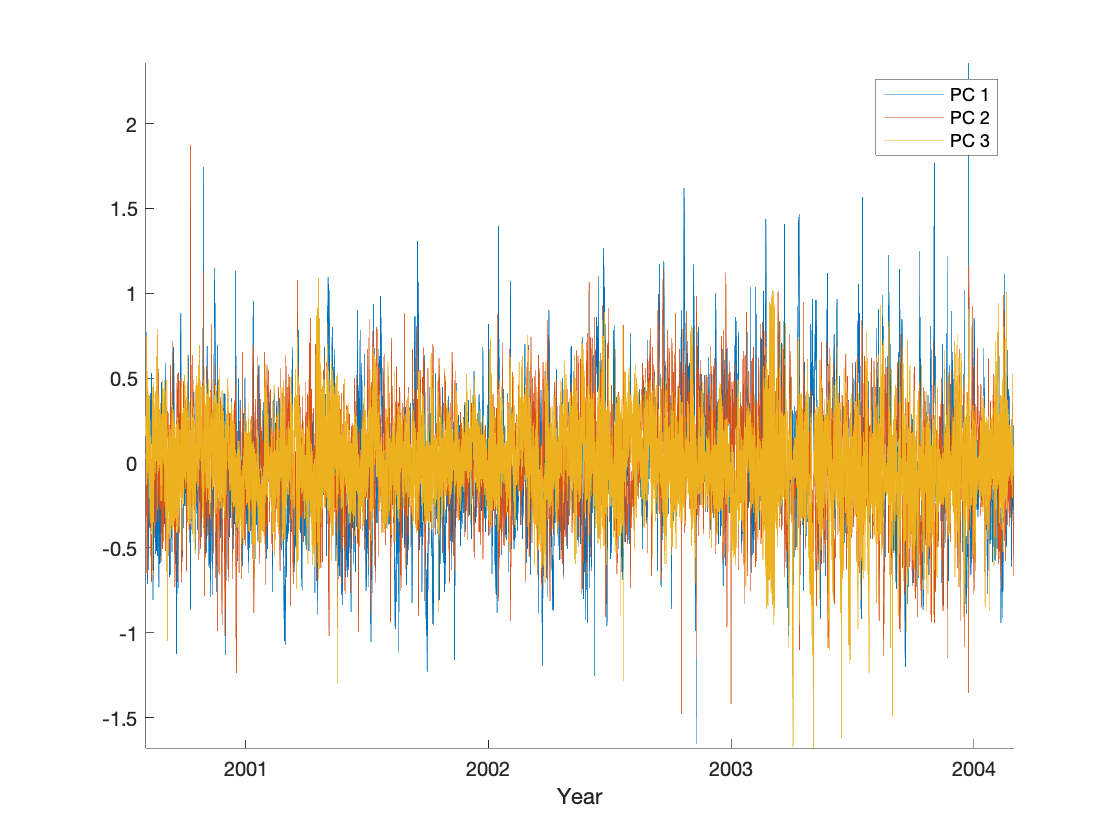

%Plot of each PC
figure
plot(P1(:,end),pc_p1(1:3,:)')
box off
axis tight
gregaxy(P1(:,end),1)
% datetick('x','keeplimits')
legend('PC 1','PC 2','PC 3')

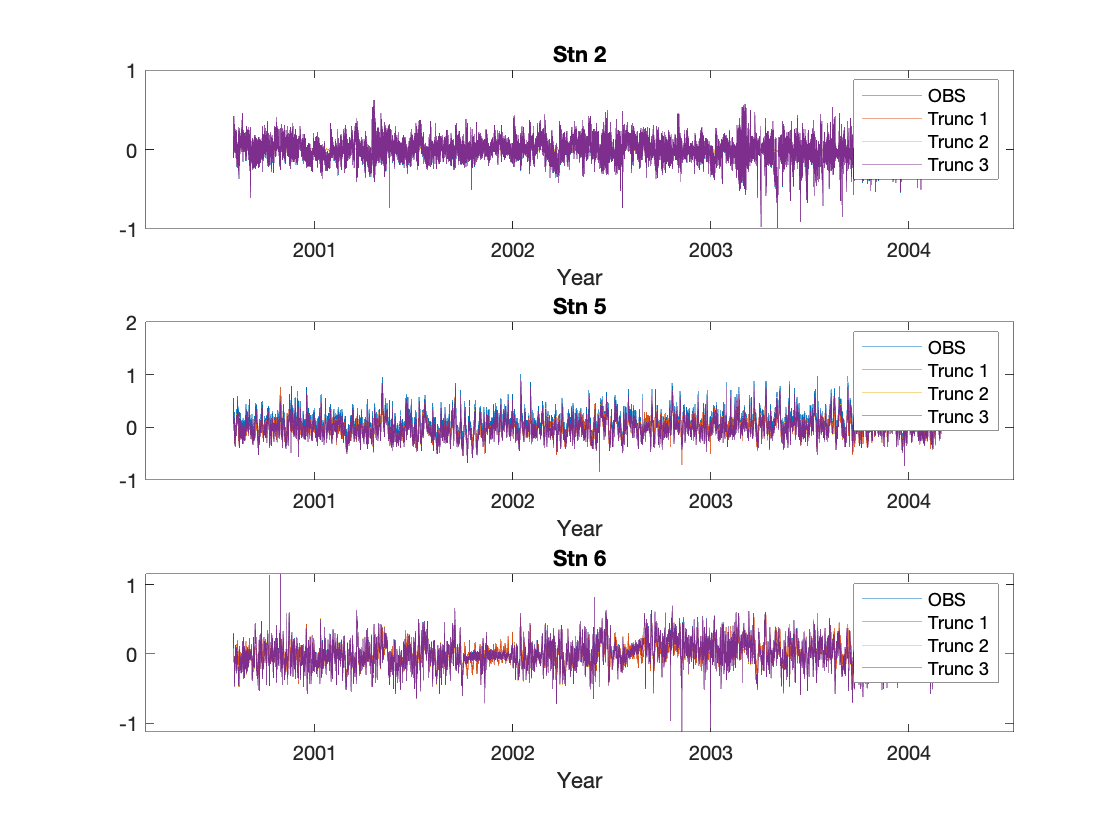

%Truncation 1, 2 and 3 (timeseries of PCs for each station)
trunc_1_p1=nan(size(P1(:,1:end-1)'));
trunc_2_p1=nan(size(P1(:,1:end-1)'));
trunc_3_p1=nan(size(P1(:,1:end-1)'));

for j=1:size(pc_p1,2)
    trunc_1_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j);      % PC1 1
    trunc_2_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j) + ... % PC1 1
                      eofmap_p1(:,1,2)*pc_p1(2,j);      % PC2 2
    trunc_3_p1(:,j) = eofmap_p1(:,1,1)*pc_p1(1,j) + ... % PC1 1
                      eofmap_p1(:,1,2)*pc_p1(2,j) + ... % PC2 2
                      eofmap_p1(:,1,3)*pc_p1(3,j);      % PC3 3
end        

figure
subplot(311)
plot(P1(:,end),P1(:,1)), 
hold on
plot(P1(:,end),trunc_1_p1(1,:)')
plot(P1(:,end),trunc_2_p1(1,:)')
plot(P1(:,end),trunc_3_p1(1,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 2')
gregaxy(P1(:,end),1)

subplot(312)
plot(P1(:,end),P1(:,2)), 
hold on
plot(P1(:,end),trunc_1_p1(2,:)')
plot(P1(:,end),trunc_2_p1(2,:)')
plot(P1(:,end),trunc_3_p1(2,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 5')
gregaxy(P1(:,end),1)

subplot(313)
plot(P1(:,end),P1(:,3)), 
hold on
plot(P1(:,end),trunc_1_p1(3,:)')
plot(P1(:,end),trunc_2_p1(3,:)')
plot(P1(:,end),trunc_3_p1(3,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 6')
gregaxy(P1(:,end),1)

%% P2 12/2007 to 03/2009 (Stn 1, 2, 3 and 4)
[a b]=size(P2);
P2_sqr=repmat(P2(:,1:end-1)',[1,1,b-1]);
P2_sqr=permute(P2_sqr,[1,3,2]);
[eofmap_p2,pc_p2,expv_p2] = eof(P2_sqr,9);
T_p2 = table(expv_p2(1),expv_p2(2),expv_p2(3),expv_p2(4),expv_p2(5),expv_p2(6),expv_p2(7),expv_p2(8),expv_p2(9), 'VariableNames', {'PC 1','PC 2','PC 3','PC 4','PC 5','PC 6','PC 7','PC 8','PC 9'})

T_p2 = 1×9 table
     PC 1      PC 2      PC 3      PC 4        PC 5          PC 6          PC 7       PC 8    PC 9
    ______    ______    ______    ______    __________    __________    __________    ____    ____

    54.651    32.495    9.1158    3.7382    5.6109e-15    3.3256e-15    1.9154e-15     0       0  


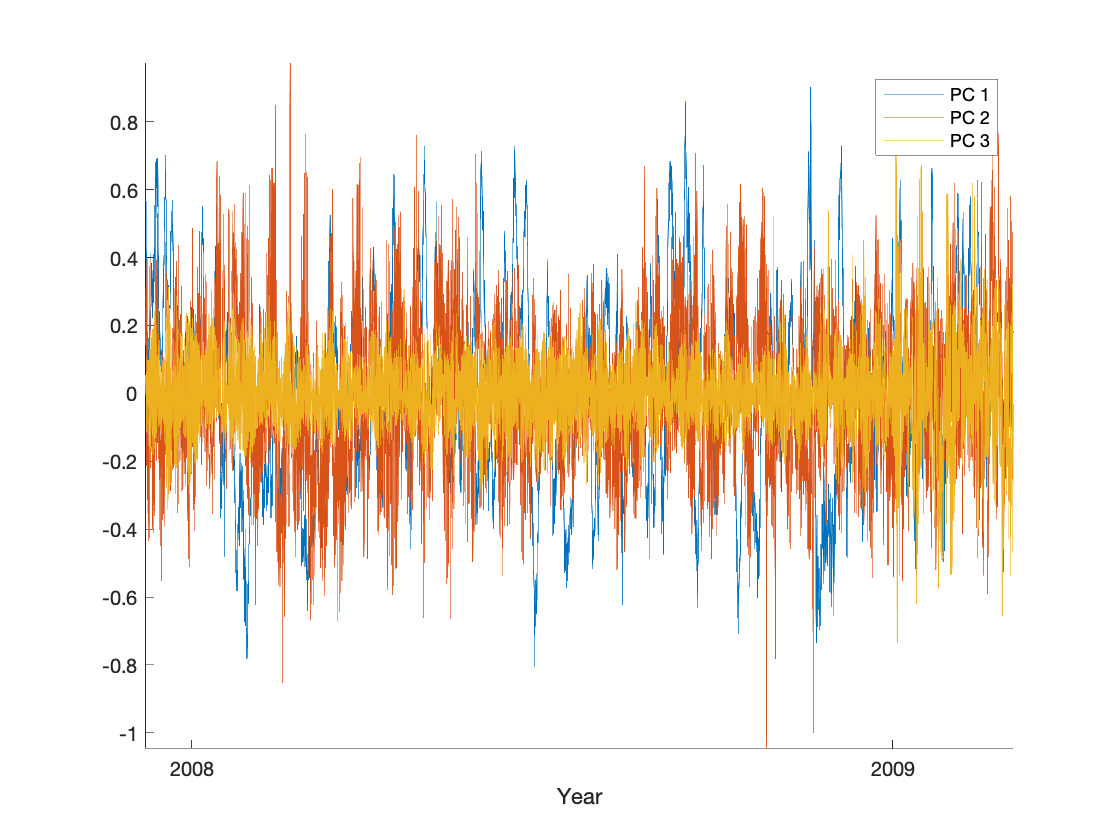

figure
plot(P2(:,end),pc_p2(1:3,:)')
box off
axis tight
gregaxy(P2(:,end),1)
% datetick('x','keeplimits')
legend('PC 1','PC 2','PC 3')

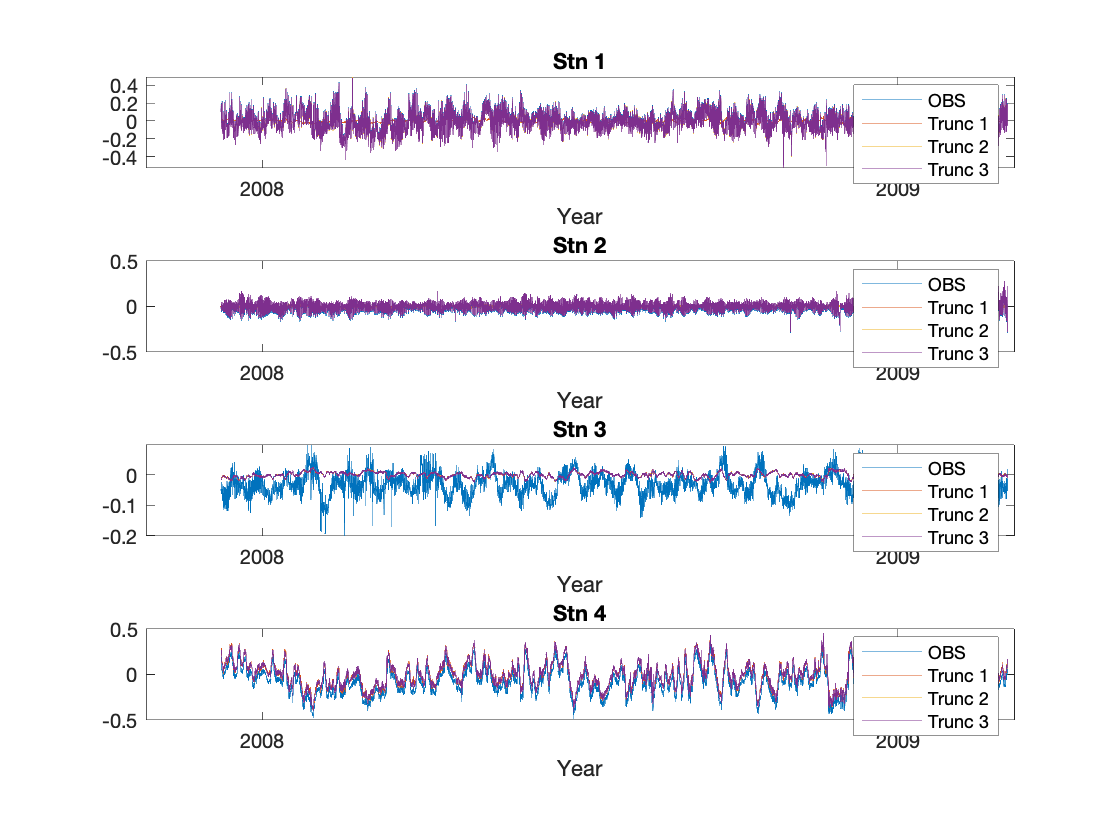

%Truncation 1, 2 and 3 (timeseries of PCs for each station)
trunc_1_p2=nan(size(P2(:,1:end-1)'));
trunc_2_p2=nan(size(P2(:,1:end-1)'));
trunc_3_p2=nan(size(P2(:,1:end-1)'));

for j=1:size(pc_p2,2)
    trunc_1_p2(:,j) = eofmap_p2(:,1,1)*pc_p2(1,j);      % PC1 1
    trunc_2_p2(:,j) = eofmap_p2(:,1,1)*pc_p2(1,j) + ... % PC1 1
                      eofmap_p2(:,1,2)*pc_p2(2,j);      % PC2 2
    trunc_3_p2(:,j) = eofmap_p2(:,1,1)*pc_p2(1,j) + ... % PC1 1
                      eofmap_p2(:,1,2)*pc_p2(2,j) + ... % PC2 2
                      eofmap_p2(:,1,3)*pc_p2(3,j);      % PC3 3
end        

figure
subplot(411)
plot(P2(:,end),P2(:,1)), 
hold on
plot(P2(:,end),trunc_1_p2(1,:)')
plot(P2(:,end),trunc_2_p2(1,:)')
plot(P2(:,end),trunc_3_p2(1,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 1')
gregaxy(P2(:,end),1)

subplot(412)
plot(P2(:,end),P2(:,2)), 
hold on
plot(P2(:,end),trunc_1_p2(2,:)')
plot(P2(:,end),trunc_2_p2(2,:)')
plot(P2(:,end),trunc_3_p2(2,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 2')
gregaxy(P2(:,end),1)

subplot(413)
plot(P2(:,end),P2(:,3)), 
hold on
plot(P2(:,end),trunc_1_p2(3,:)')
plot(P2(:,end),trunc_2_p2(3,:)')
plot(P2(:,end),trunc_3_p2(3,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 3')
gregaxy(P2(:,end),1)

subplot(414)
plot(P2(:,end),P2(:,4)), 
hold on
plot(P2(:,end),trunc_1_p2(4,:)')
plot(P2(:,end),trunc_2_p2(4,:)')
plot(P2(:,end),trunc_3_p2(4,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 4')
gregaxy(P2(:,end),1)


%% P3 10/2007 to 01/2014 (Stn 2, 3 and 4)
[a b]=size(P3);
P3_sqr=repmat(P3(:,1:end-1)',[1,1,b-1]);
P3_sqr=permute(P3_sqr,[1,3,2]);
[eofmap_p3,pc_p3,expv_p3] = eof(P3_sqr,9);
T_p3 = table(expv_p3(1),expv_p3(2),expv_p3(3),expv_p3(4),expv_p3(5),expv_p3(6),expv_p3(7),expv_p3(8),expv_p3(9), 'VariableNames', {'PC 1','PC 2','PC 3','PC 4','PC 5','PC 6','PC 7','PC 8','PC 9'})

T_p3 = 1×9 table
     PC 1      PC 2      PC 3     PC 4      PC 5       PC 6    PC 7      PC 8       PC 9
    ______    ______    ______    ____    _________    ____    ____    _________    ____

    62.962    25.189    11.849     0      4.781e-15     0       0      3.739e-16     0  


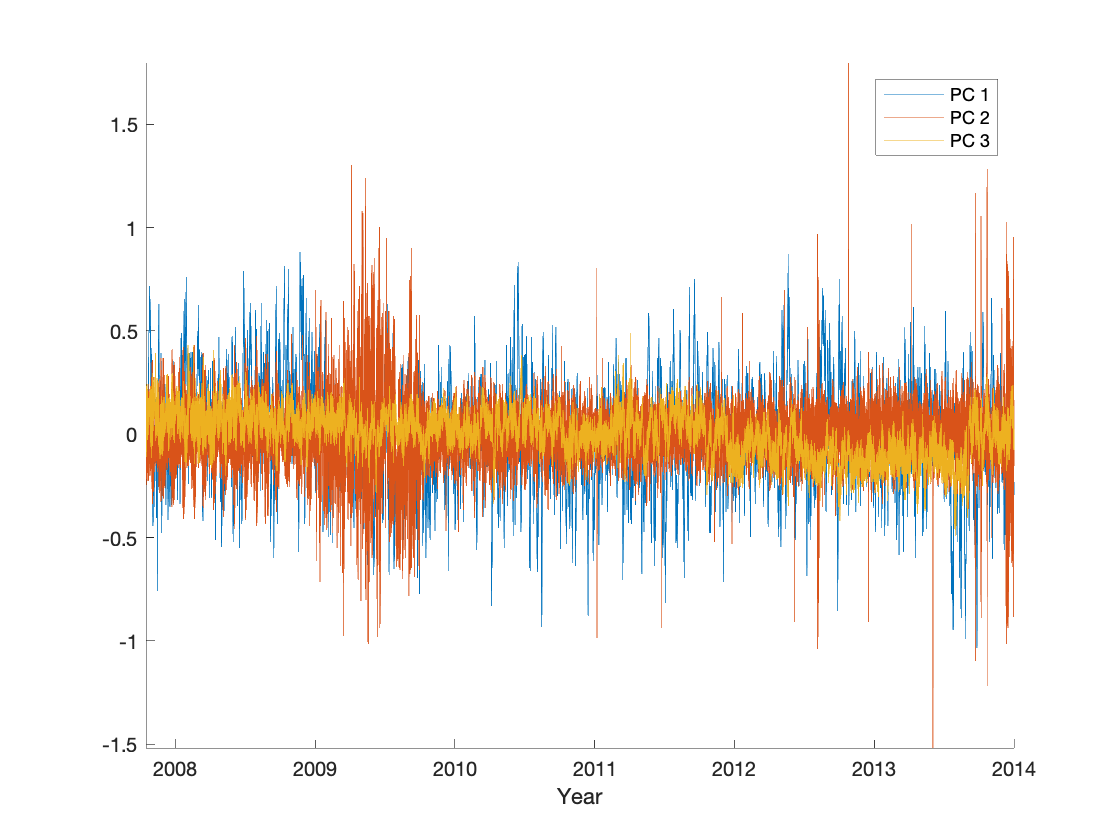

figure
plot(P3(:,end),pc_p3(1:3,:)')
box off
axis tight
gregaxy(P3(:,end),1)
% datetick('x','keeplimits')
legend('PC 1','PC 2','PC 3')

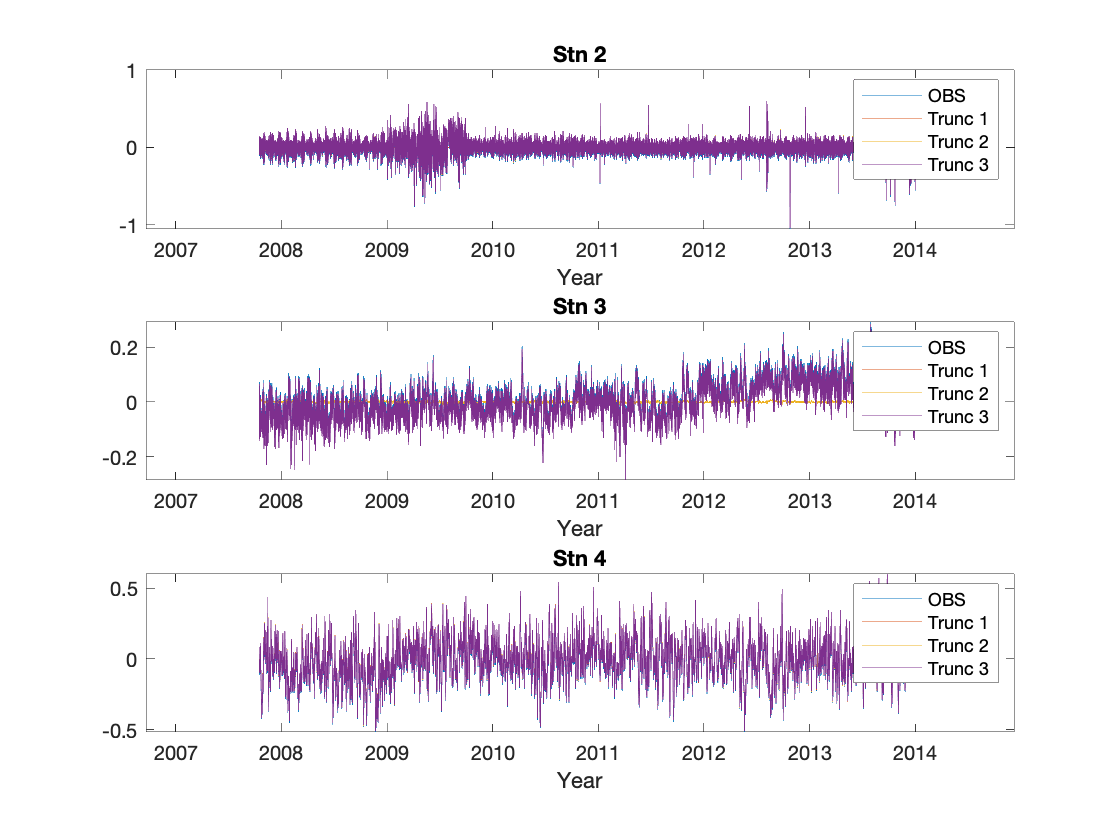

%Truncation 1, 2 and 3 (timeseries of PCs for each station)
trunc_1_p3=nan(size(P3(:,1:end-1)'));
trunc_2_p3=nan(size(P3(:,1:end-1)'));
trunc_3_p3=nan(size(P3(:,1:end-1)'));

for j=1:size(pc_p3,2)
    trunc_1_p3(:,j) = eofmap_p3(:,1,1)*pc_p3(1,j);      % PC1 1
    trunc_2_p3(:,j) = eofmap_p3(:,1,1)*pc_p3(1,j) + ... % PC1 1
                      eofmap_p3(:,1,2)*pc_p3(2,j);      % PC2 2
    trunc_3_p3(:,j) = eofmap_p3(:,1,1)*pc_p3(1,j) + ... % PC1 1
                      eofmap_p3(:,1,2)*pc_p3(2,j) + ... % PC2 2
                      eofmap_p3(:,1,3)*pc_p3(3,j);      % PC3 3
end        

figure
subplot(311)
plot(P3(:,end),P3(:,1)), 
hold on
plot(P3(:,end),trunc_1_p3(1,:)')
plot(P3(:,end),trunc_2_p3(1,:)')
plot(P3(:,end),trunc_3_p3(1,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 2')
gregaxy(P3(:,end),1)

subplot(312)
plot(P3(:,end),P3(:,2)), 
hold on
plot(P3(:,end),trunc_1_p3(2,:)')
plot(P3(:,end),trunc_2_p3(2,:)')
plot(P3(:,end),trunc_3_p3(2,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 3')
gregaxy(P3(:,end),1)

subplot(313)
plot(P3(:,end),P3(:,3)), 
hold on
plot(P3(:,end),trunc_1_p3(3,:)')
plot(P3(:,end),trunc_2_p3(3,:)')
plot(P3(:,end),trunc_3_p3(3,:)')
legend('OBS','Trunc 1','Trunc 2','Trunc 3')
title('Stn 4')
gregaxy(P3(:,end),1)